# ARMA estimation

## Exercise 54

In this exercise, we construct the dataset that we will use for our time series analysis. We will use data from Federal Reserve Economic Data (FRED), which is a data hub by the St Luis branch of the Federal Reserve System in the US. You find millions of time series from the webpage. 

In order to load data from FRED, we can use the `fetch` function. The function `fetch` requires the `Datafeed` `toolbox`. You can try the code below to check if you have installed or not: 

d = fetch(fred(), 'DEXUSEU')

d = struct with fields:
                 Title: ' U.S. / Euro Foreign Exchange Rate'
              SeriesID: ' DEXUSEU'
                Source: ' Board of Governors of the Federal Reserve System (US)'
               Release: ' H.10 Foreign Exchange Rates'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Daily'
                 Units: ' U.S. Dollars to One Euro'
             DateRange: ' 1999-01-04 to 2020-01-17'
           LastUpdated: ' 2020-01-21 4:12 PM CST'
                 Notes: ' Noon buying rates in New York City for cable transfers payable in foreign currencies.'
                  Data: [5490×2 double]


To install the `Datafeed` `toolbox`, just follow the instructions in the command window. 

Here we have loaded the historic exchange rate between the USD and EUR. Notice that the data comes in a *struct* form. Let's plot this series:

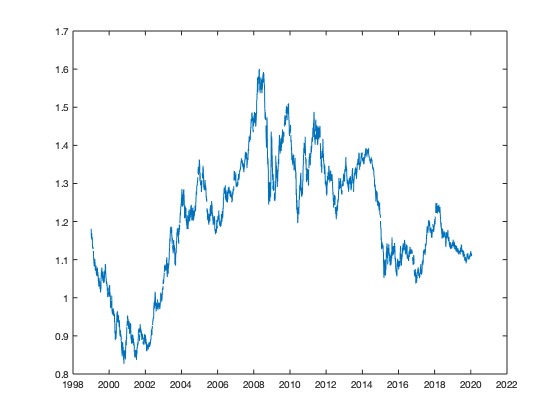

plot(d.Data(:,1), d.Data(:,2))
datetick('x')

The exercise asks us to download data on 1 year and 10 years US government bond rates and to construct the term premium as the difference in yields on 10 years and 1 year bonds. This difference is used as a benchmark for the compensation that an investor would demand for holding a bond with longer maturity. An investor would demand a premium for longer maturity, because he needs to be compensated for the duration risk.

Now let's get the data on these rates:

gs1 = fetch(fred(), 'GS1')

gs1 = struct with fields:
                 Title: ' 1-Year Treasury Constant Maturity Rate'
              SeriesID: ' GS1'
                Source: ' Board of Governors of the Federal Reserve System (US)'
               Release: ' H.15 Selected Interest Rates'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Monthly'
                 Units: ' Percent'
             DateRange: ' 1953-04-01 to 2019-12-01'
           LastUpdated: ' 2020-01-02 8:18 PM CST'
                 Notes: ' Averages of business days. For further information regarding treasury constant maturity data, please refer to http://www.federalreserve.gov/releases/h15/current/h15.pdf and http://www.treasury.gov/resource-center/data-chart-center/interest-rates/Pages/yieldmethod.aspx.'
                  Data: [801×2 double]


gs10 = fetch(fred(), 'GS10')

gs10 = struct with fields:
                 Title: ' 10-Year Treasury Constant Maturity Rate'
              SeriesID: ' GS10'
                Source: ' Board of Governors of the Federal Reserve System (US)'
               Release: ' H.15 Selected Interest Rates'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Monthly'
                 Units: ' Percent'
             DateRange: ' 1953-04-01 to 2019-12-01'
           LastUpdated: ' 2020-01-02 8:18 PM CST'
                 Notes: ' Averages of business days. For further information regarding treasury constant maturity data, please refer to the Board of Governors (http://www.federalreserve.gov/releases/h15/current/h15.pdf) and the Treasury (http://www.treasury.gov/resource-center/data-chart-center/interest-rates/Pages/yieldmethod.aspx).'
                  Data: [801×2 double]


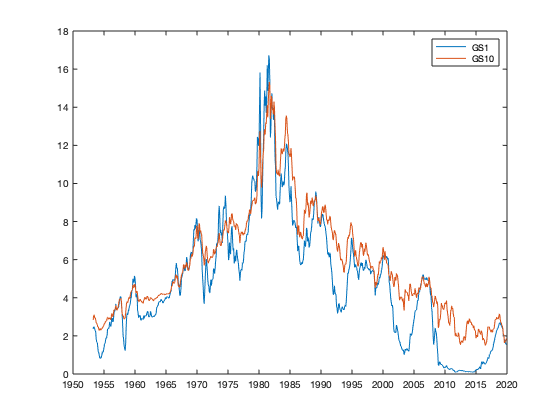

plot(gs1.Data(:,1), gs1.Data(:,2))
datetick('x')
hold on
plot(gs10.Data(:,1),gs10.Data(:,2))
hold off
legend(gs1.SeriesID, gs10.SeriesID)

Let's do some economic history. Interest rates measure the pulse of the economy. They tell us whether the economy is overheating, what happens to prices or whether we are in a prolonged slump. The short run interest rate in the US is a policy rate, althought it depends on the monetary policy regime. Since the early 1990s, the central banks have controlled the economy by setting the short term interest rate. The central bank reduces the policy rate to stimulate the economy. The idea is that a lower interest rate reduces the cost of capital, it is cheaper to borrow funds. And the lower cost of capital will stimulate investment. Longer term interest rates are partially affected by the short term interest rates, because longer term interest rates can be decomposed into a chain of short rates. But over most of history, longer term interest rates have been freely floating, without inference from a central bank. That changed fairly recently in the US. Since the Great Recession of 2009, the Federal Reserve has begun to purchase longer dated US government debt. And by doing so, they have depressed the longer run interest rates and the longer run term premium. 

We finish off the first exercise by constructing the term premium:

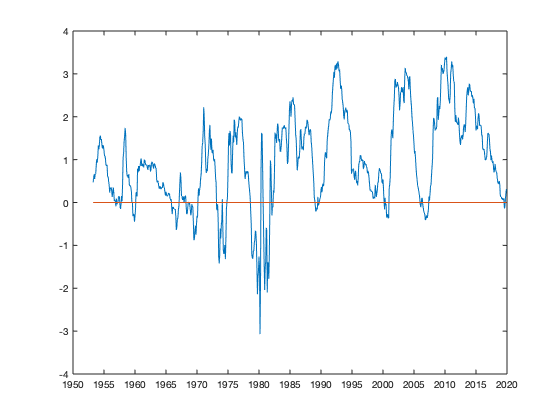

tp = gs10.Data(:,2) - gs1.Data(:,2);
plot(gs10.Data(:,1),[tp, zeros(numel(tp),1)])
datetick('x')

The term premium looks reasonably stable. Assuming stationarity seems like a fair assumption; at least it is not an explosive time series. So now we will investigate which model best describes its intertemporal features.

## Exercise 55 

We will now estimate time series models using the `armaxfilter` from the MFE toolboxthat that Kevin has coded for us. 

help armaxfilter

  ARMAX(P,Q) estimation
 
  USAGE:
    [PARAMETERS]=armaxfilter(Y,CONSTANT,P,Q)
    [PARAMETERS, LL, ERRORS, SEREGRESSION, DIAGNOSTICS, VCVROBUST, VCV, LIKELIHOODS, SCORES]
                =armaxfilter(Y,CONSTANT,P,Q,X,STARTINGVALS,OPTIONS,HOLDBACK,SIGMA2)
 
  INPUTS:
    Y            - A column of data
    CONSTANT     - Scalar variable: 1 to include a constant, 0 to exclude
    P            - Non-negative integer vector representing the AR orders to include in the model.
    Q            - Non-negative integer vector representing the MA orders to include in the model.
    X            - [OPTIONAL]  a T by K  matrix of exogenous variables. These line up exactly with
                     the Y's and if they are time series, you need to shift them down by 1 place,
                     i.e. pad the bottom with 1 observation and cut off the top row [ T by K].  For
                     example, if you want to include X(t-1) as a regressor, Y(t) should line up
                     with X(t-

Let's begin with an AR(1) model:

% The AR(1) model
[p,~,~,~,~,vcv_robust] = armaxfilter(tp, 1,1,0);
disp('Parameters:')

Parameters:


disp(p)

     0.027042
      0.97184



These are the parameters for the AR(1) model. Now let's get the standard errors and check for the significance of these estimates:

% Getting the standard errors:
se = sqrt(diag(vcv_robust));
disp('Standard Errors:')

Standard Errors:


disp(se)

     0.019206
     0.013307



% Calculating the T-Stats:
tstats = p./se;
disp('T-Stats')

T-Stats


disp(tstats)

        1.408
       73.031



We find a highly significant coefficient for the AR component. It is fairly close to the one, so we might need to test later for the presence of a unit root.

## Exercise 56

Next, we fit the MA(5) model. While the AR(1) model is just a simple regression model, the MA(5) model includes the lags of the error term. So it is not the standard least squares estimation anymore. Instead we need to maximize the likelihood function (minimize the objective function). You can see that a minimization problem is solved by iterations:

armaxfilter(tp,1,0,1:5)


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          7          238.63                           106
     1         14          106.85       0.957512           70.4      
     2         21         79.2361        1.48128           51.8      
     3         28          69.829       0.251488           17.3      
     4         35         68.4226       0.198691           4.22      
     5         42         68.0529       0.131831           3.67      
     6         49         67.8896      0.0648595           1.83      
     7         56         67.8062      0.0752088           1.47      
     8         63         67.7646       0.047887          0.936      
     9         70         67.7408      0.0569323          0.693      
    10         77         67.7264      0.0442405          0.604      
    11         84         67.7176      0.0507731          0.587      
    12         91         67.711

ans =       0.93574
       1.5125
       1.4224
       1.1882
      0.75142
      0.29786


If we would not want to see the iterations of the minimization problem, then we can set the options:

options.Display = 'none';
armaxfilter(tp,1,0,1:5,[],[],options)

ans =       0.93574
       1.5125
       1.4224
       1.1882
      0.75142
      0.29786


Ok. Enough playing around. It is time to estimate the coefficients:

% The MA(5) model:
[p,~,~,~,~,vcv_robust] = armaxfilter(tp, 1,0,1:5, [],[],options);
disp('Parameters:')

Parameters:


disp(p)

      0.93574
       1.5125
       1.4224
       1.1882
      0.75142
      0.29786



Now let's get the standard errors. Again, we will compute the test statistics for the parameters as well.

% Getting the standard errors:
se = sqrt(diag(vcv_robust));
disp('Standard Errors:')

Standard Errors:


disp(se)

     0.065433
      0.19959
      0.33012
       0.1609
      0.14162
      0.13546



% Calculating the T-Stats:
tstats = p./se;
disp('T-Stats')

T-Stats


disp(tstats)

       14.301
       7.5782
       4.3088
       7.3847
        5.306
       2.1988



We see that the coefficients are significant. This confirms that there is an interesting intertemporal structure in the data. 

## Exercise 57

Now let's estimate an ARMA(1,1) model:

% The ARMA(1,1) model:
[p,~,~,~,~,vcv_robust] = armaxfilter(tp, 1,1,1, [],[],options);
disp('Parameters:')

Parameters:


disp(p)

     0.047482
      0.95074
      0.42009



Again, getting the standard errors and checking the significance:

% Getting the standard errors:
se = sqrt(diag(vcv_robust));
disp('Standard Errors:')

Standard Errors:


disp(se)

     0.027628
     0.020174
      0.12366



% Calculating the T-Stats:
tstats = p./se;
disp('T-Stats')

T-Stats


disp(tstats)

       1.7186
       47.127
       3.3973



The ARMA(1,1) suggests that both the AR and the MA components are necessary. In this section, we have just estimated different models. This is a very simple thing to do, thanks to Kevin's toolbox, which gives us the `armaxfilter` function to estimate ARMA models. 

Finally, we should just save the term premium data for the next exercises:

save term_premium tp